setup,
addpath('Q:\dataAvendano_Apr5\CARACTERIZACION');

# Phantom 1: 8% gelatin, 2% cornstarch

## Parameters

% Set as desired
acq1 = 23:27;
acq2 = 12:16;

% Sample properties
rho = 1050;
c = 1517.8;

% Reference properties: water
rhor = 1000;
cr = 1482.97;

% Phantom width [cm]
d = 1.81;

D1 = 2*(rhor*cr)/((rhor*cr)+(rho*c)); % Tcw
D2 = 2*(rho*c)/((rhor*cr)+(rho*c)); % Twc
TL = (D1*D2)^2; % Transmission_loss

## Acquisition 1: Just water

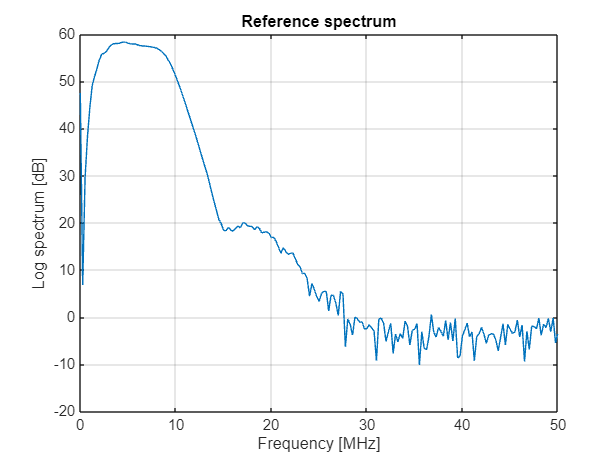

N = 2000; % Number of samples
powerSpectrum = zeros(N,length(acq1));

for ii = 1:length(acq1)
    data_plexi = readmatrix(sprintf('TEK000%d.CSV', acq1(ii)),"Range", "A17:B20016");
    time_vec = data_plexi(:,1); %[s]
    volt_vec = data_plexi(:,2); %[V]
    N = length(volt_vec); 
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    powerSpectrum(:,ii) = abs(fft(volt_vec)).^2;
end
spectrumRef = mean(powerSpectrum,2);
logSpectrumRef = db(spectrumRef,"power");
f = (0:N-1)/N*Fs;

figure
plot(f*1e-6,logSpectrumRef)
xlim([0 50])
xlabel('Frequency [MHz]')
ylabel('Log spectrum [dB]')
grid on
title('Reference spectrum')

## Acquisition 2: Water and phantom

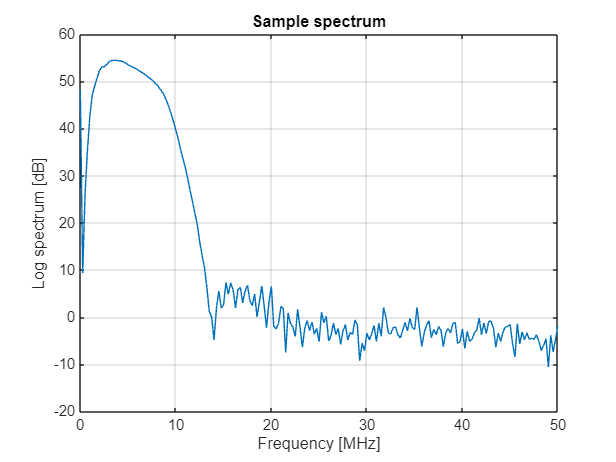

N = 2000; % Number of samples
powerSpectrum = zeros(N,length(acq2));

for ii = 1:length(acq2)
    data_plexi = readmatrix(sprintf('TEK000%d.CSV', acq2(ii)),"Range", "A17:B20016");
    time_vec = data_plexi(:,1); %[s]
    volt_vec = data_plexi(:,2); %[V]
    N = length(volt_vec); 
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    powerSpectrum(:,ii) = abs(fft(volt_vec)).^2;
end
spectrumSam = mean(powerSpectrum,2)/TL;
logSpectrumSam = db(spectrumSam,"power");
f = (0:N-1)/N*Fs;

figure
plot(f*1e-6,logSpectrumSam)
xlim([0 50])
xlabel('Frequency [MHz]')
ylabel('Log spectrum [dB]')
grid on
title('Sample spectrum')

## Attenuation curve and fitting

% Limits for curve fitting
fL = 4e6; fH = 9e6;

attCurve = (logSpectrumRef - logSpectrumSam)/(2*d);
freqRange = f(f>=fL & f<=fH) / 1e6;
attRange = attCurve(f>=fL & f<=fH);

fitFunc = fittype('alpha0 + alpha1*f', 'independent', 'f', 'coefficients', {'alpha0', 'alpha1'});

[fitResult, gof] = fit(freqRange(:), attRange(:), fitFunc);

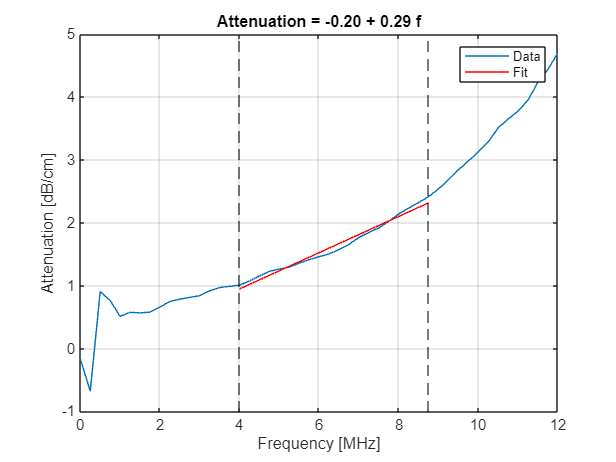


figure; 
plot(f*1e-6, attCurve); 
hold on
plot(freqRange, fitResult(freqRange), 'r-');
xline(min(freqRange), 'k--')
xline(max(freqRange), 'k--')
hold off
xlabel ("Frequency [MHz]"),
xlim([0 12]), 
ylabel ("Attenuation [dB/cm]")
grid on
legend('Data', 'Fit');
fitString = sprintf("Attenuation = %.2f + %.2f f",fitResult.alpha0,fitResult.alpha1);
title(fitString)

# Phantom 2: Agar

## Parameters

% Set as desired
acq1 = 23:27;
acq2 = 28:32;

% Sample properties
rho = 1050;
c = 1500.8;

% Reference properties: water
rhor = 1000;
cr = 1483.275; % Set according to temperature

% Phantom width [cm]
d = 2.03;

D1 = 2*(rhor*cr)/((rhor*cr)+(rho*c)); % Tcw
D2 = 2*(rho*c)/((rhor*cr)+(rho*c)); % Twc
TL = (D1*D2)^2; % Transmission_loss

## Acquisition 1: Just water

N = 2000; % Number of samples
powerSpectrum = zeros(N,length(acq1));

for ii = 1:length(acq1)
    data_plexi = readmatrix(sprintf('TEK000%d.CSV', acq1(ii)),"Range", "A17:B20016");
    time_vec = data_plexi(:,1); %[s]
    volt_vec = data_plexi(:,2); %[V]
    N = length(volt_vec); 
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    powerSpectrum(:,ii) = abs(fft(volt_vec)).^2;
end
spectrumRef = mean(powerSpectrum,2);
logSpectrumRef = db(spectrumRef,"power");
f = (0:N-1)/N*Fs;

figure
plot(f*1e-6,logSpectrumRef)
xlim([0 50])
xlabel('Frequency [MHz]')
ylabel('Log spectrum [dB]')
grid on
title('Reference spectrum')

## Acquisition 2: Water and phantom

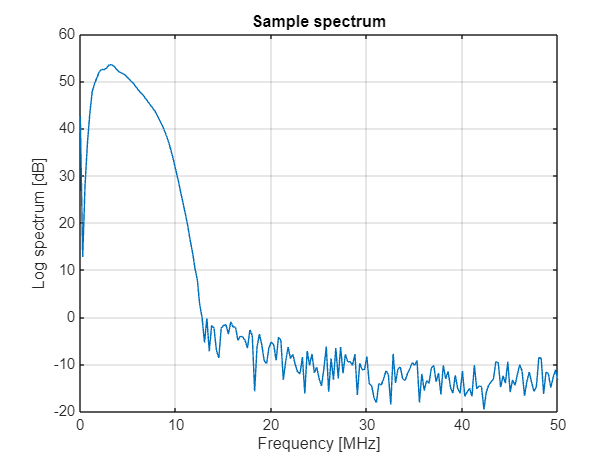

N = 2000; % Number of samples
powerSpectrum = zeros(N,length(acq2));

for ii = 1:length(acq2)
    data_plexi = readmatrix(sprintf('TEK000%d.CSV', acq2(ii)),"Range", "A17:B20016");
    time_vec = data_plexi(:,1); %[s]
    volt_vec = data_plexi(:,2); %[V]
    N = length(volt_vec); 
    Fs = 1/((time_vec(end)-time_vec(1))/N); % sampling frequency [samples/s]
    powerSpectrum(:,ii) = abs(fft(volt_vec)).^2;
end
spectrumSam = mean(powerSpectrum,2)/TL;
logSpectrumSam = db(spectrumSam,"power");
f = (0:N-1)/N*Fs;

figure
plot(f*1e-6,logSpectrumSam)
xlim([0 50])
xlabel('Frequency [MHz]')
ylabel('Log spectrum [dB]')
grid on
title('Sample spectrum')

## Attenuation curve and fitting

% Limits for curve fitting
fL = 4e6; fH = 9e6;

attCurve = (logSpectrumRef - logSpectrumSam)/(2*d);
freqRange = f(f>=fL & f<=fH) / 1e6;
attRange = attCurve(f>=fL & f<=fH);

fitFunc = fittype('alpha0 + alpha1*f', 'independent', 'f', 'coefficients', {'alpha0', 'alpha1'});

[fitResult, gof] = fit(freqRange(:), attRange(:), fitFunc);

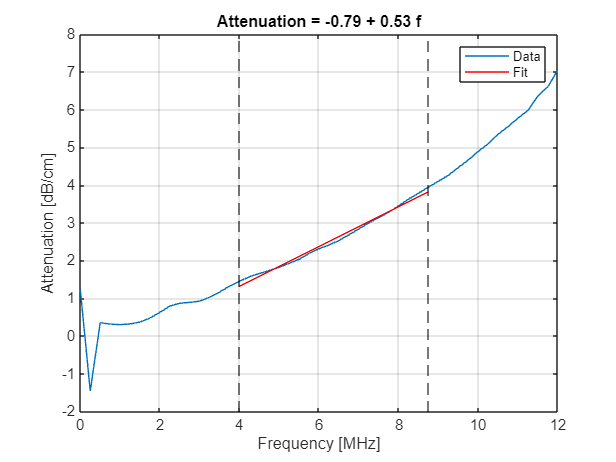


figure; 
plot(f*1e-6, attCurve); 
hold on
plot(freqRange, fitResult(freqRange), 'r-');
xline(min(freqRange), 'k--')
xline(max(freqRange), 'k--')
hold off
xlabel ("Frequency [MHz]"),
xlim([0 12]), 
ylabel ("Attenuation [dB/cm]")
grid on
legend('Data', 'Fit');
fitString = sprintf("Attenuation = %.2f + %.2f f",fitResult.alpha0,fitResult.alpha1);
title(fitString)